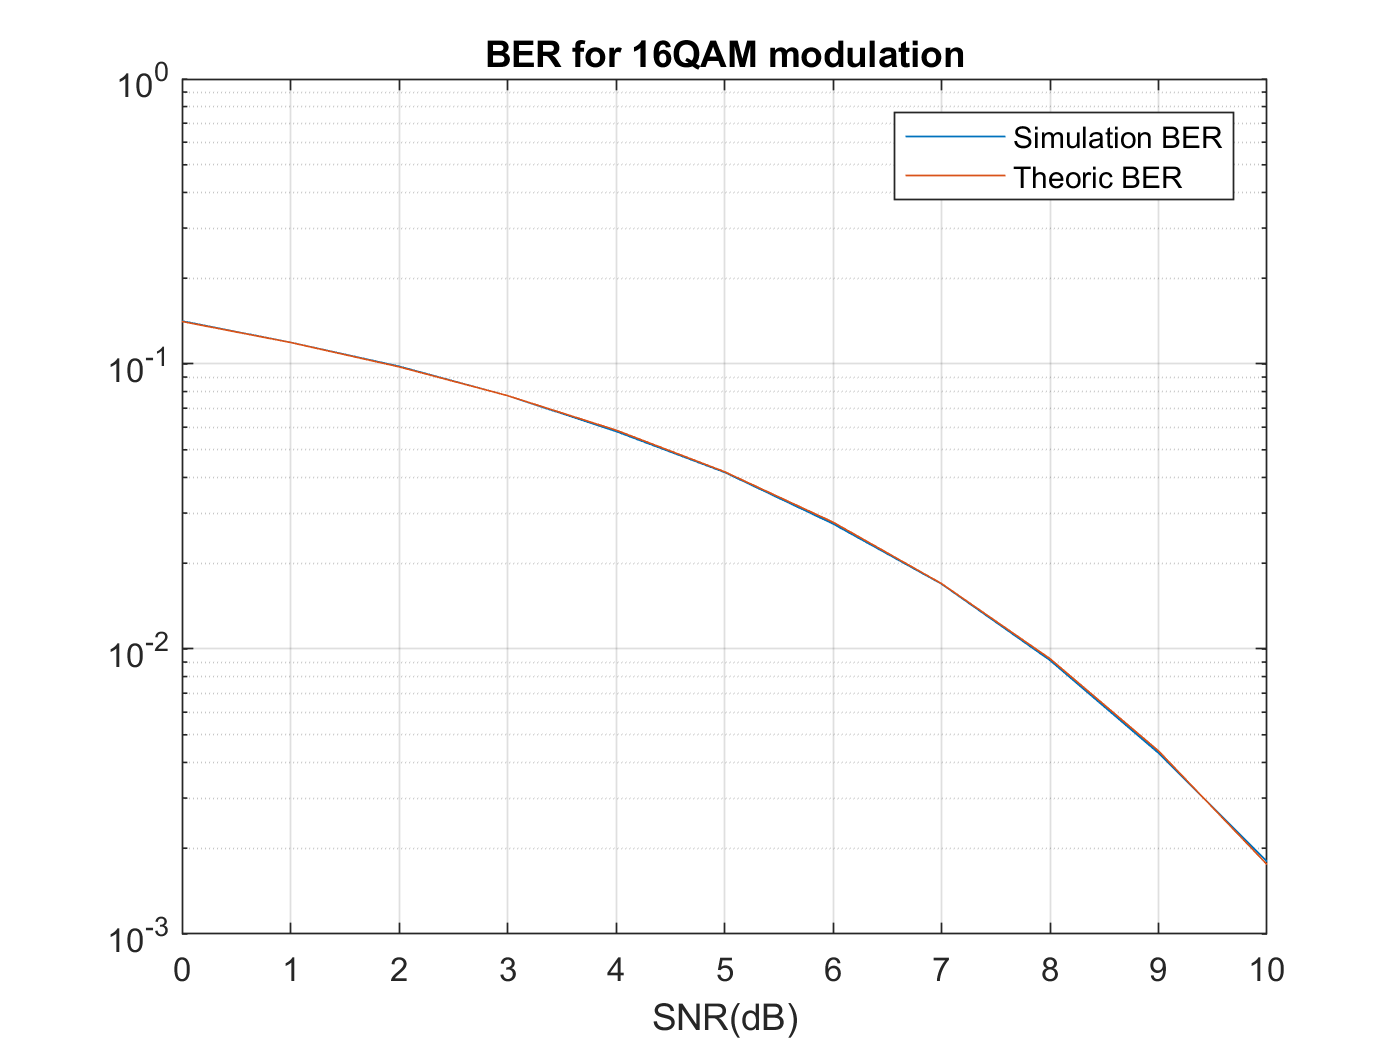

% dcl_init();
clc;clear;close all;
rng(1)
pkt_size = 1e5;
smpl_per_symbl = 8;
modulation = 'qam';
chnl_delay_in_smpl = 0;
chnl_phase_offset = 0;
k = 4;
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
pulse_name = 'root_raised_cosine';
beta = 0.9;
span_in_symbl = 6;
BER = zeros(11,1);

for l = 0:10
    BER(l+1) = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,l,fs,beta,span_in_symbl);
end
snr_db = 0:10;
[BER_m, ~] = berawgn((snr_db).', 'qam', 2^k);


figure
semilogy(snr_db,BER )
hold on
semilogy(snr_db,BER_m)
hold off
legend('Simulation BER', 'Theoric BER')
title('BER for 16QAM modulation')
xlabel('SNR(dB)')
grid

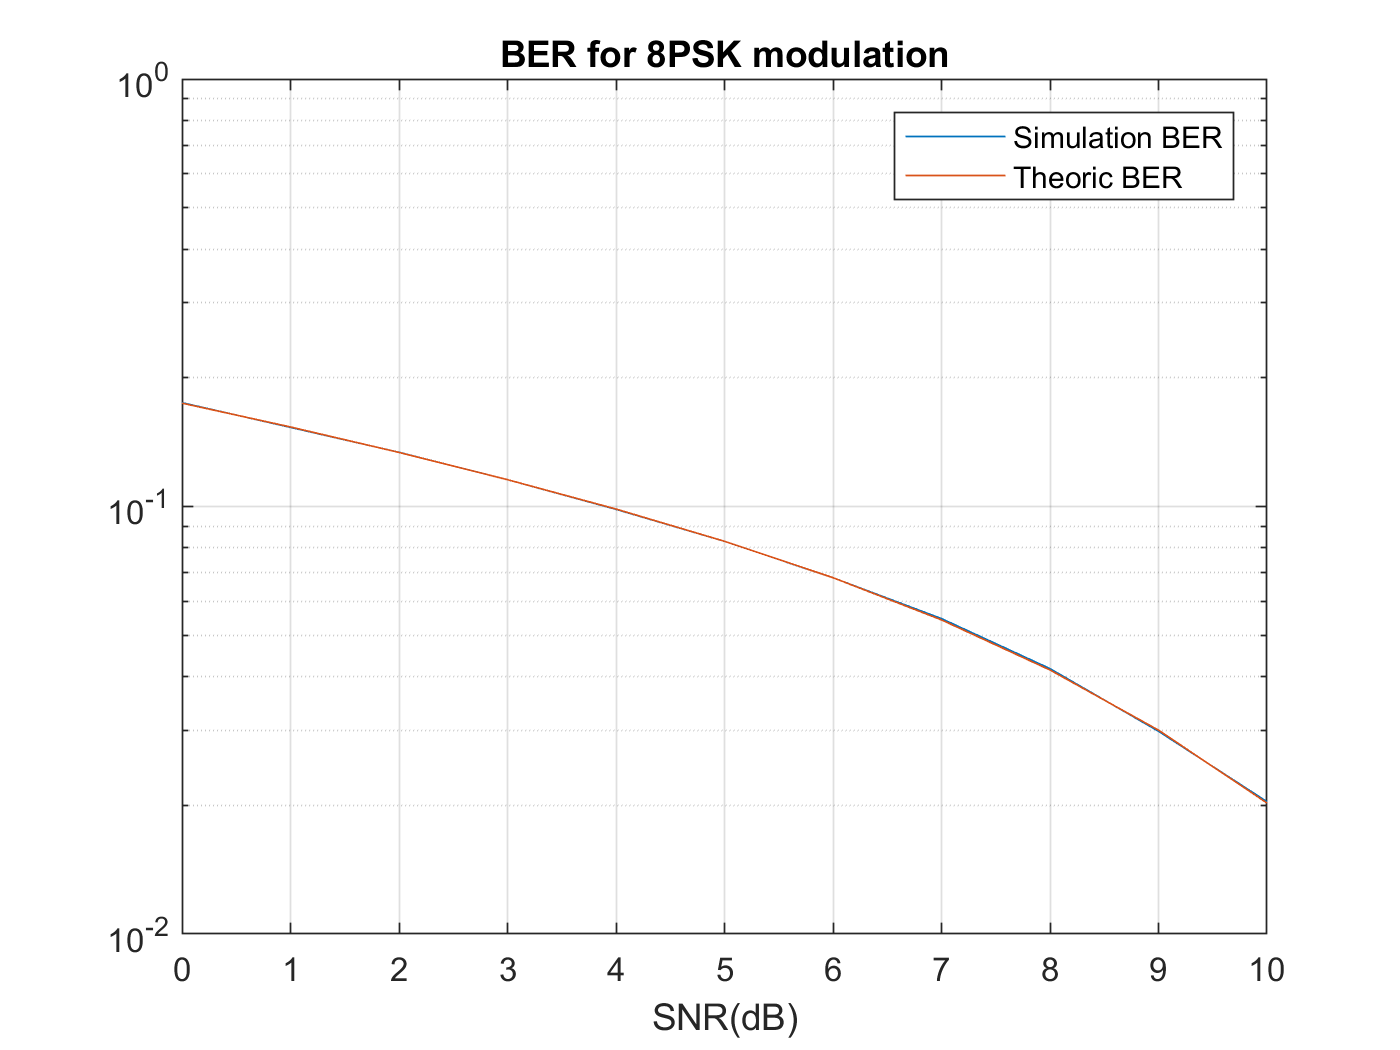

% % dcl_init();
rng(1)
pkt_size = 100000;
smpl_per_symbl = 8;
modulation = 'psk';
chnl_delay_in_smpl = 0;
chnl_phase_offset = 0;
k = 4;

pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
pulse_name = 'root_raised_cosine';
beta = 0.9;
span_in_symbl = 6;
BER = zeros(11,1);

for l = 0:10
    BER(l+1) = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,l,fs,beta,span_in_symbl);
end
snr_db = 0:10;
[BER_m, ~] = berawgn((snr_db).', 'psk', 2^k,'nondiff');


figure
semilogy(snr_db,BER )
hold on
semilogy(snr_db,BER_m)
hold off
legend('Simulation BER', 'Theoric BER')
title('BER for 8PSK modulation')
xlabel('SNR(dB)')
grid

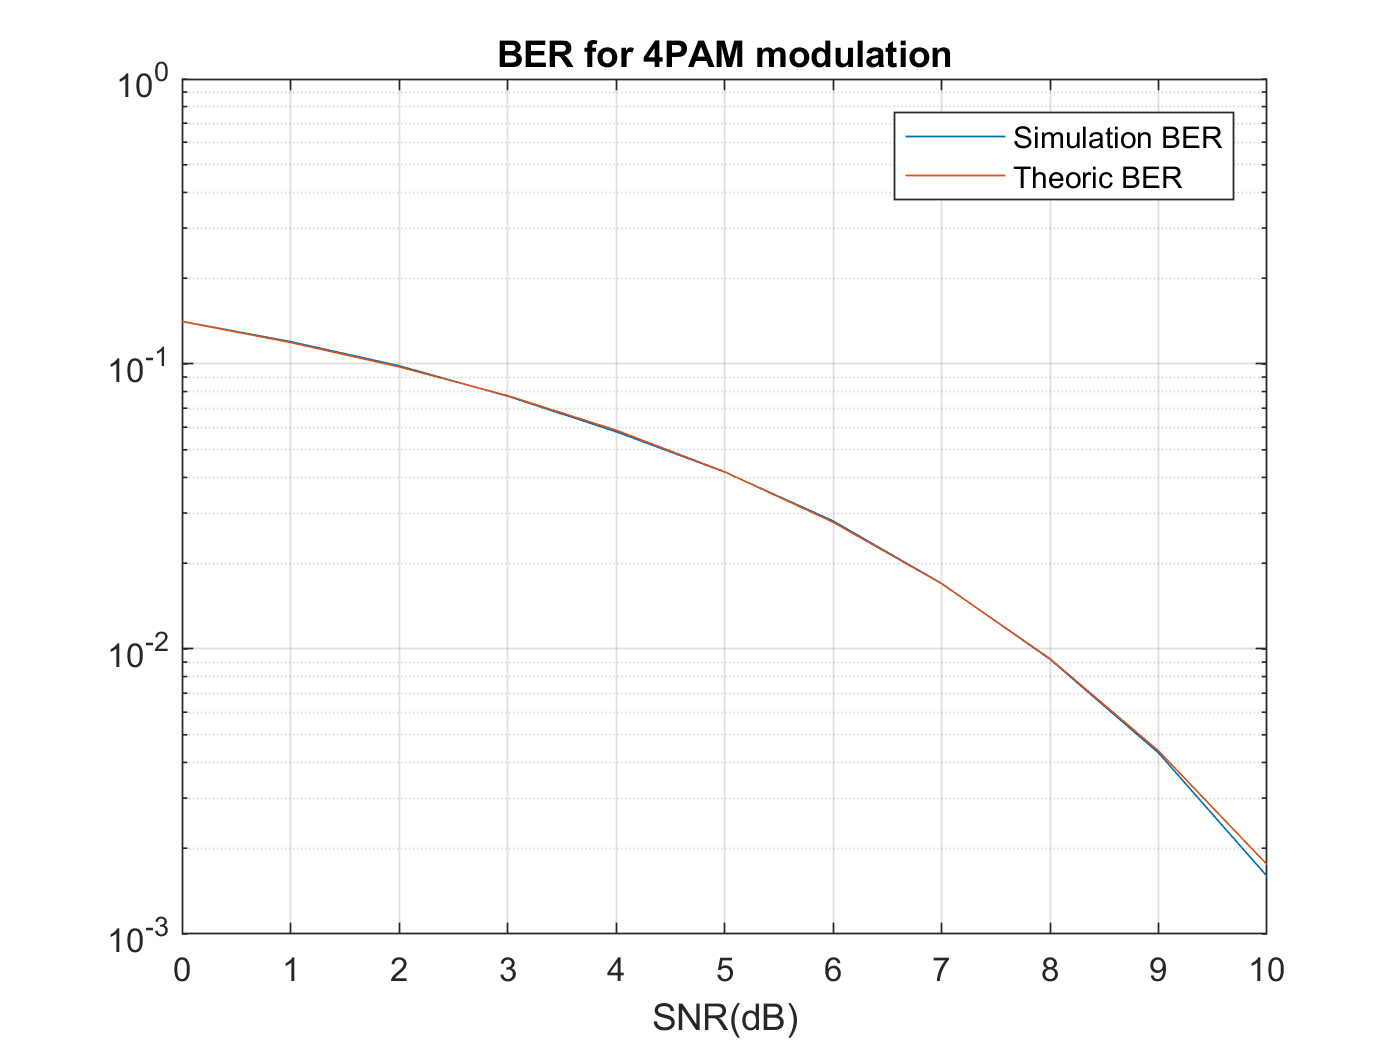

% % dcl_init();
rng(1)
pkt_size = 100000;
smpl_per_symbl = 8;
modulation = 'pam';
chnl_delay_in_smpl = 0;
chnl_phase_offset = 0;
k = 2;

pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1e6;
pulse_name = 'root_raised_cosine';
beta = 0.9;
span_in_symbl = 6;
BER = zeros(11,1);


for l = 0:10
    BER(l+1) = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,l,fs,beta,span_in_symbl);
end
snr_db = 0:10;
[BER_m, ~] = berawgn((snr_db).', 'pam', 2^k);


figure
semilogy(snr_db,BER )
hold on
semilogy(snr_db,BER_m)
hold off
legend('Simulation BER', 'Theoric BER')
title('BER for 4PAM modulation')
xlabel('SNR(dB)')
grid

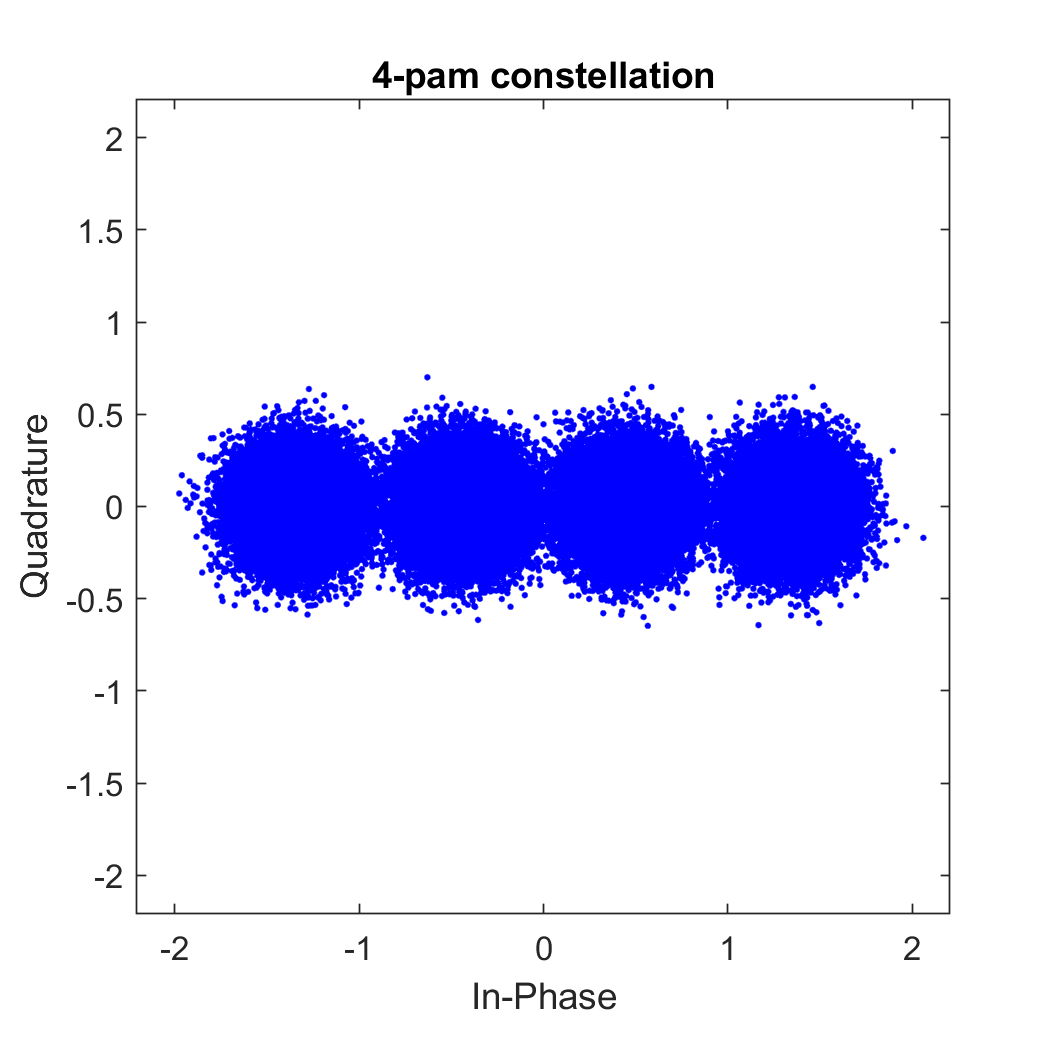

rng(1)
pkt_size = 100000;
smpl_per_symbl = 8;
modulation = 'pam';
chnl_delay_in_smpl = 0;
chnl_phase_offset = 0;
k = 2;
pulse_name = 'root_raised_cosine';
pulse_shape_mode = 'conv';
rx_mode = 'correlator';
fs = 1;
beta = 0.9;
span_in_symbl = 6;
BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,10,fs,beta,span_in_symbl);

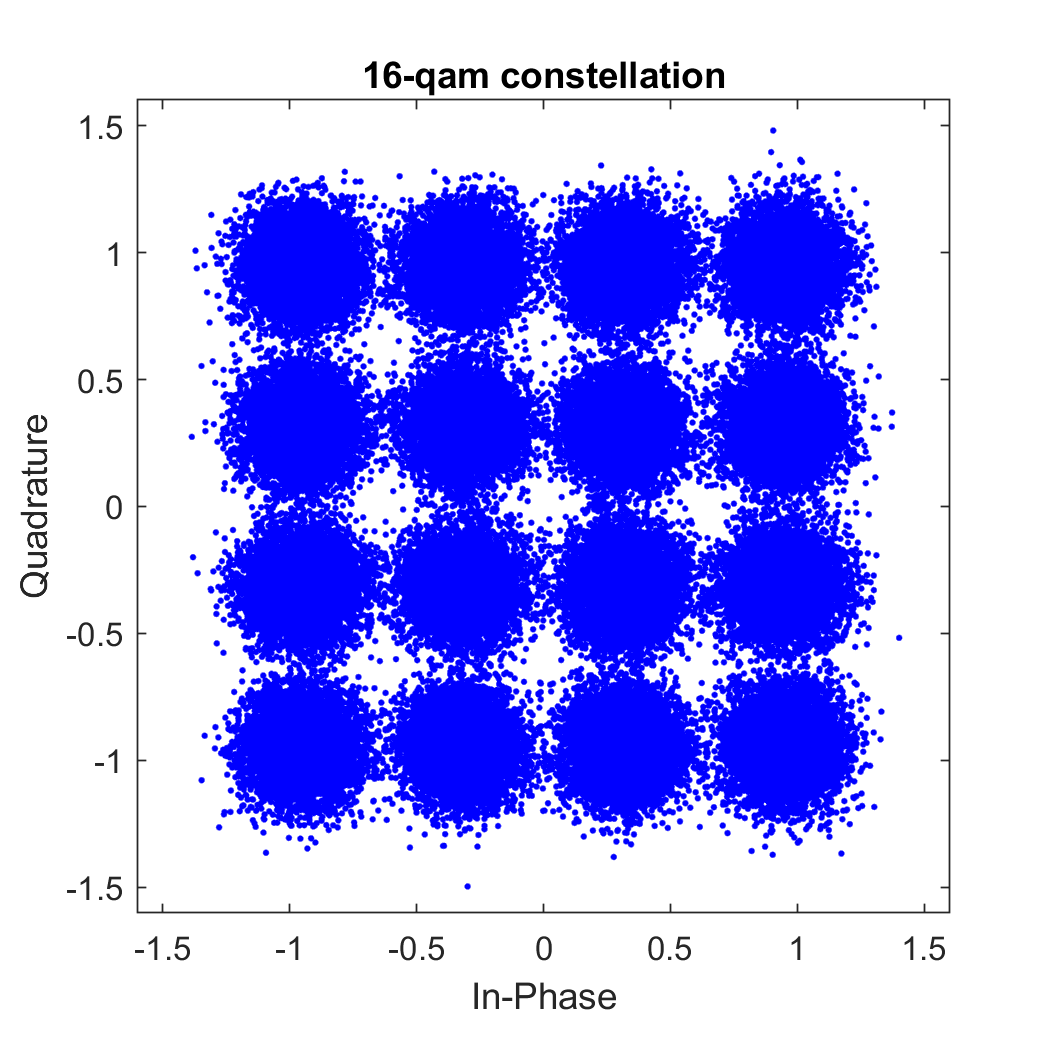

modulation = 'qam';
k = 4;
BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,10,fs,beta,span_in_symbl);

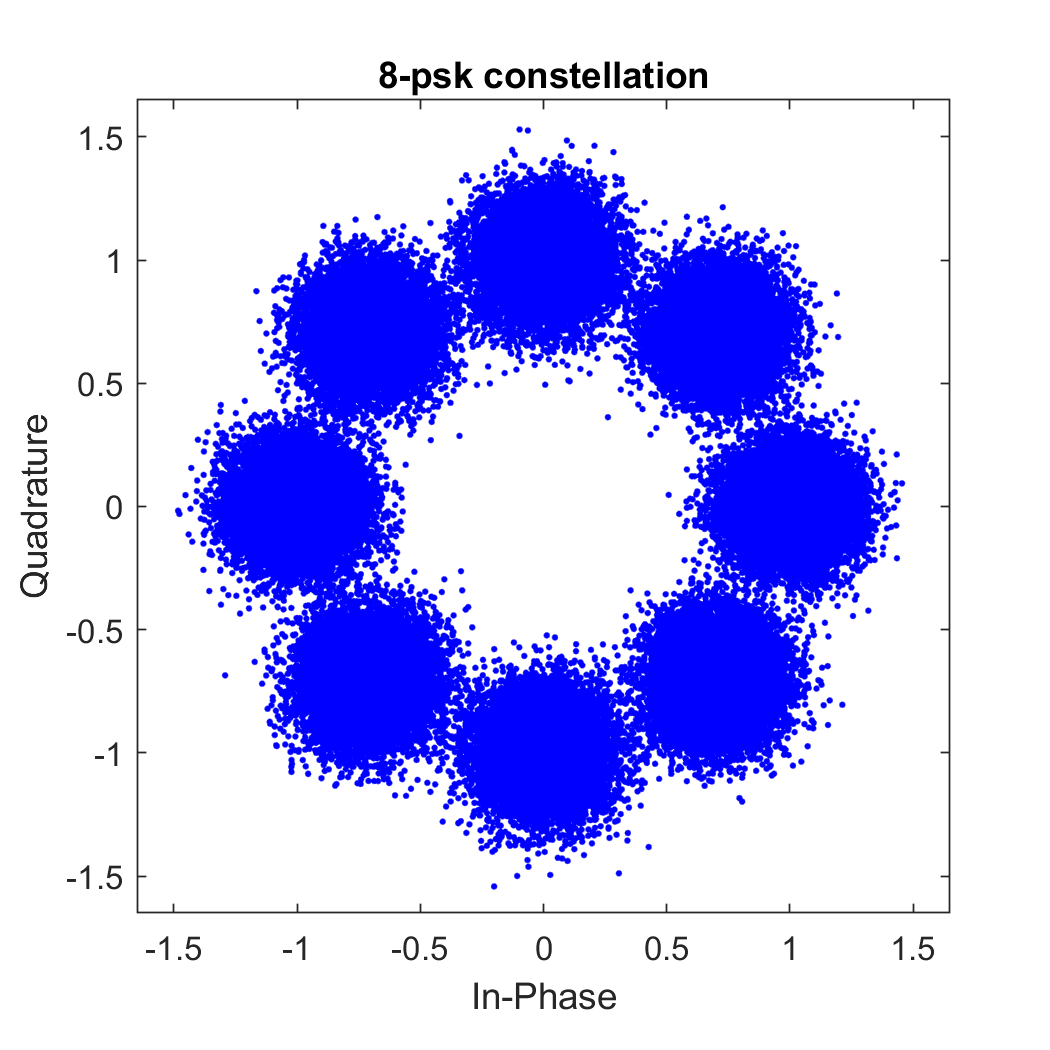

modulation = 'psk';
k = 3;
BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,10,fs,beta,span_in_symbl);

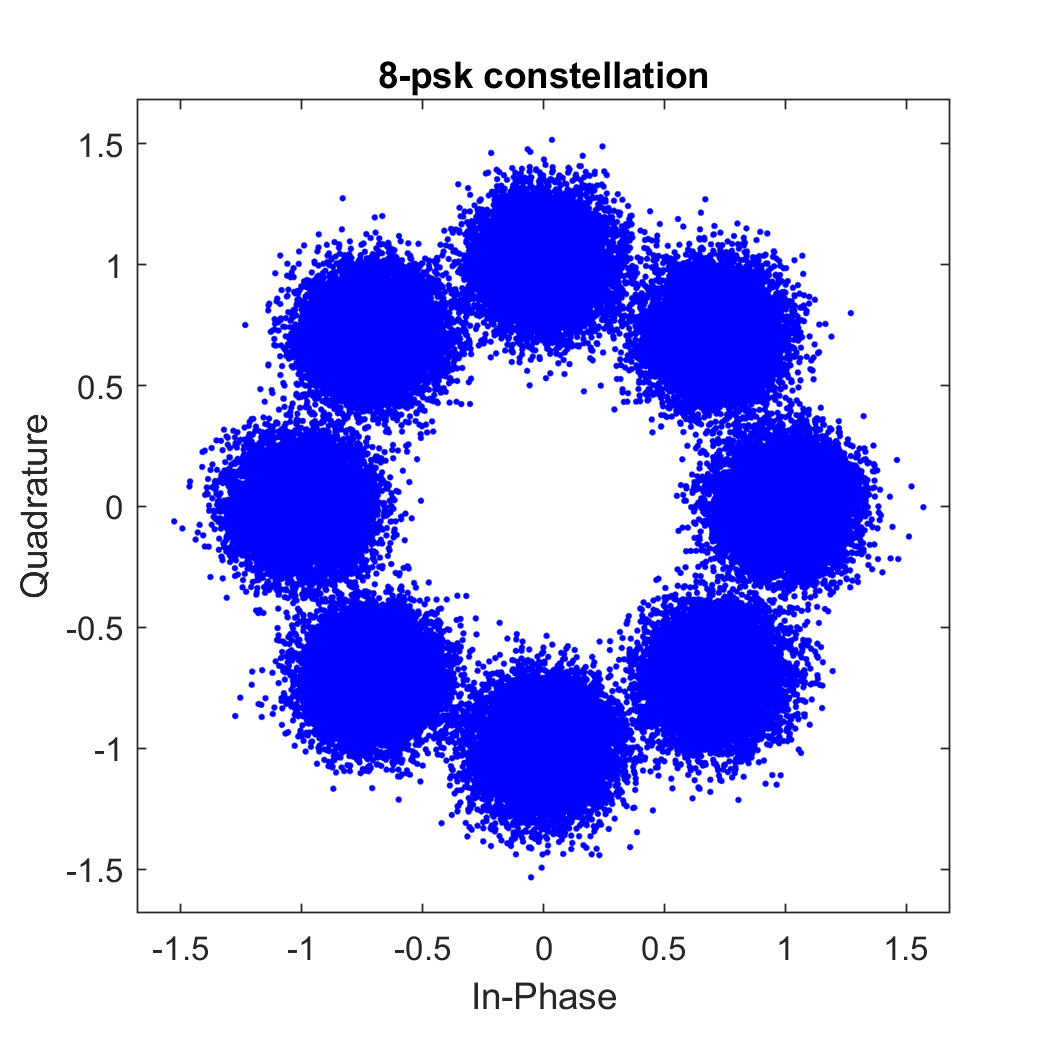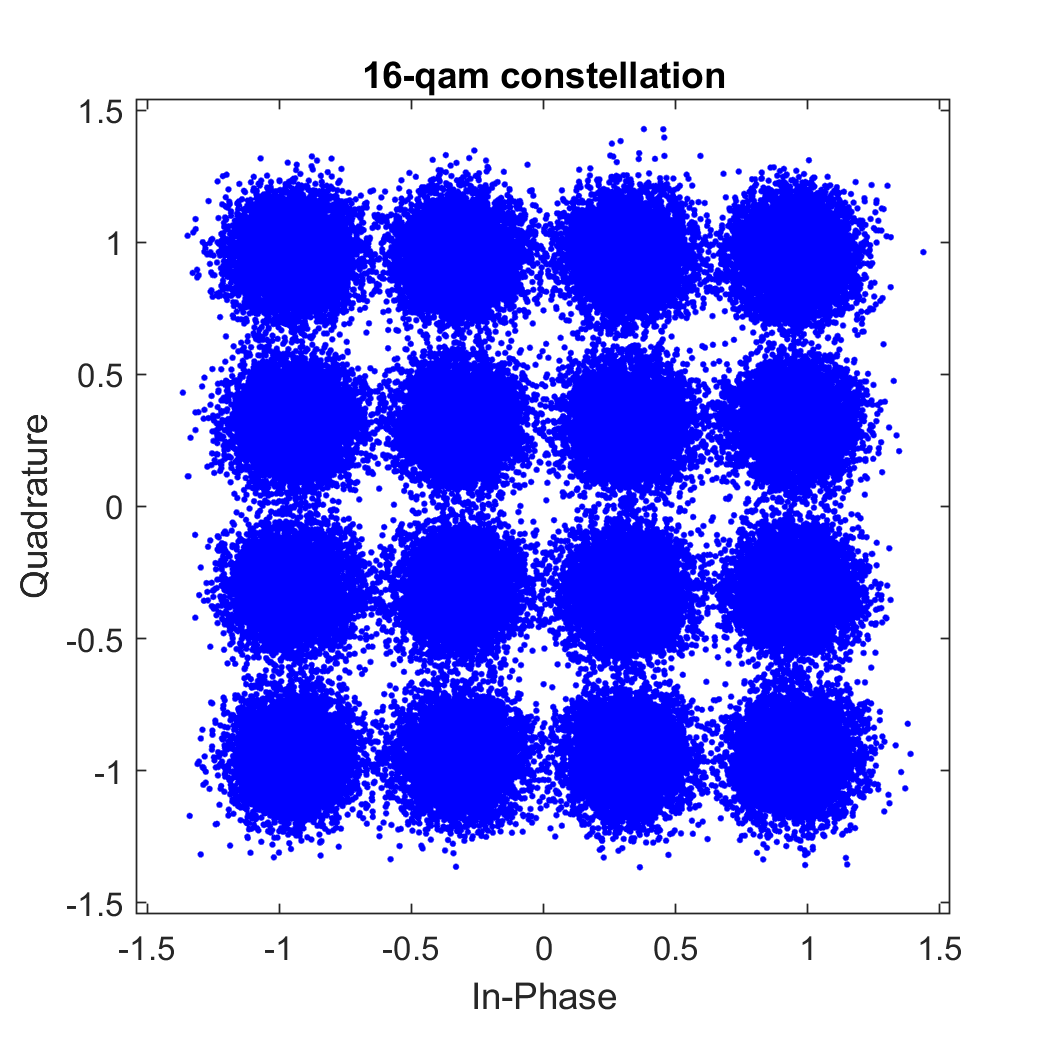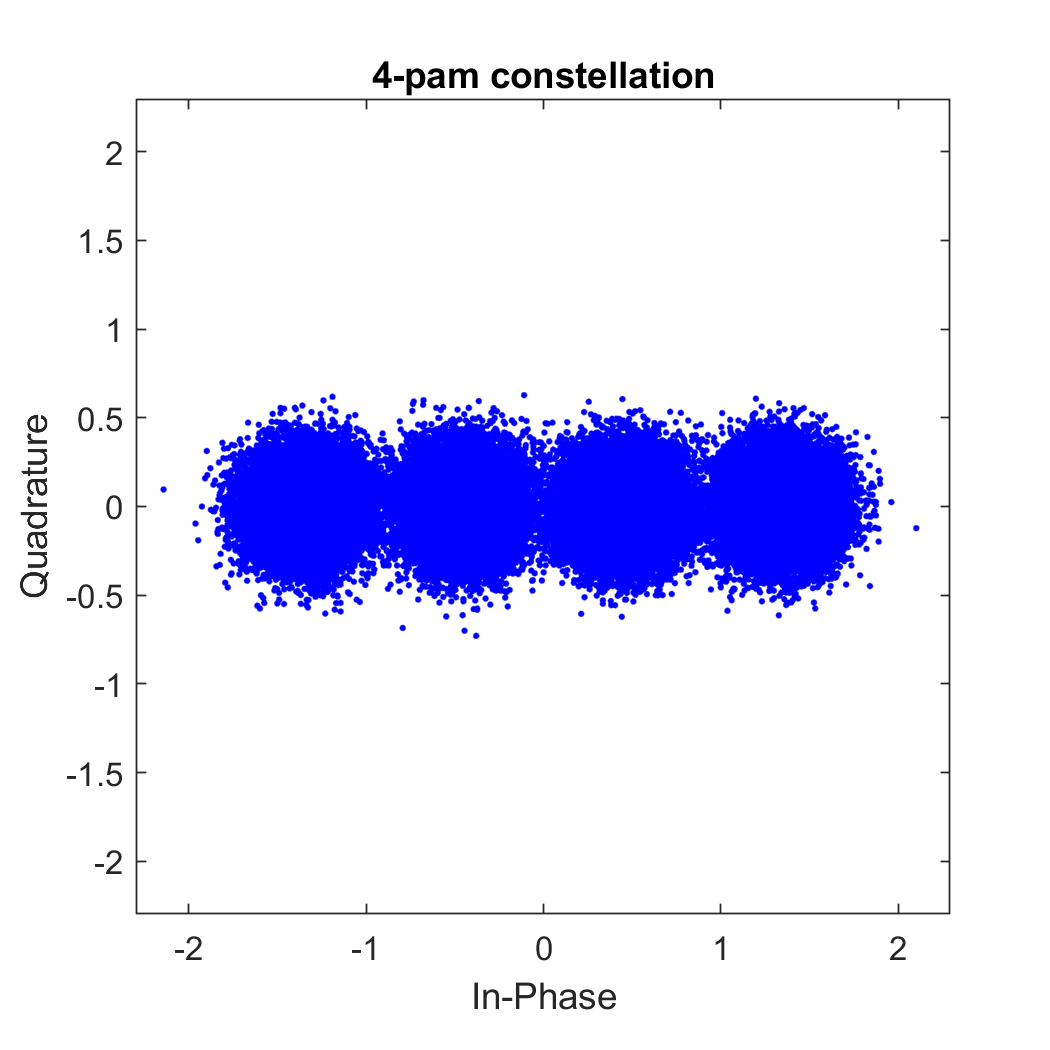

used functions

function [ber] = BER_calc(pkt_size,smpl_per_symbl,modulation,chnl_delay_in_smpl,chnl_phase_offset,k,pulse_name,pulse_shape_mode,rx_mode,snr_db,fs,beta,span_in_symbl)
    b_tx = bit_gen(pkt_size, k);
    flg_gray_encode=1;
    if flg_gray_encode == 1
        b_gray = gray_code(k);
        sym_idx = zeros(pkt_size, 1);
        b_gray_dec = bi2de(b_gray, 'left-msb');
        b_tx_dec = bi2de(b_tx, 'left-msb');
        for c = 1:2^k
            sym_idx(b_tx_dec == b_gray_dec(c)) = c;
        end
    else
        sym_idx = bi2de(b_tx,'left-msb')+1;
    end
    [cons, Es_avg] = constellation(2^k, modulation);
    mod_sym = cons(sym_idx);
    [tx_smpl, cons_] = pulse_modulation(sym_idx, modulation, 2^k, fs, smpl_per_symbl, pulse_name, pulse_shape_mode,beta,span_in_symbl);
    
    % if pkt_size==10
    %     plot( real(tx_smpl))
    %     hold on
    %     plot( imag(tx_smpl))
    %     hold off
    %     legend('real part', 'imaginary part', 'Location', 'south')
    % end
    
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
    rx_smpl = tx_smpl_delayed * exp(1i * chnl_phase_offset);
    Eb = Es_avg / k;
    var_noise = Eb / power(10, (snr_db / 10));
    noise_smpl = (sqrt(var_noise/2) * randn(length(tx_smpl), 1) + 1i * sqrt(var_noise/2) * randn(length(tx_smpl), 1));
    rx_smpl_noise = noise_smpl + rx_smpl;
    
    
    rx_smpl = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, 2^k, fs, smpl_per_symbl, pulse_name , rx_mode,beta,span_in_symbl, 0);
    
    
    if flg_gray_encode == 1
        det_bit = b_gray(det_sym_idx,:);
    else
         det_bit = de2bi(det_sym_idx-1, 'left-msb');
    end
    ber = sum(sum((det_bit ~= b_tx))) / (pkt_size * k);
end
function [b] = bit_gen(N, k)
b = int32(randi([0,1],N,k));
end

function [b_gray] = gray_code(k)
    b_gray = ones(2^k, k);
    b_gray(1:2^(k-1), 1) = 0;
    if k ~= 1
        tmp = gray_code(k-1);
        b_gray(1:2^(k-1), 2:k) = tmp;
        b_gray(2^(k-1) + 1:2^k, 2:k) = flip(tmp, 1);
    end
end

function [cons, Es_avg] = constellation(M, modulation)
    l = (1:M)';
    switch modulation
        case 'pam'
            cons = 2*l - 1 - M;
        case 'psk'
            cons = cos(2*pi*(l-1)/M) +1i*sin(2*pi*(l-1)/M);
        case 'qam'
            M1 = 2^ceil(log2(sqrt(M)));
            M2 = 2^floor(log2(sqrt(M)));
            cons1 = -(M1-1):2:(M1-1);
            cons2 = -(M2-1):2:(M2-1);
            cons = cons1 + 1i*cons2';
            for i = 1:size(cons, 2)
                if mod(i, 2) == 0
                    cons(:, i) = cons(end:-1:1, i);
                end
            end
            cons = cons(:);
        otherwise
            disp('invalid modulation')
    end
    Es_avg = sum(abs(cons).^2)/M;
    cons = cons/sqrt(Es_avg);
    Es_avg = 1;
end

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl,beta,span_in_symbl, varargin)
    t = (0:smpl_per_symbl-1).'/fs;
    Ts = smpl_per_symbl/fs;
    switch pulse_name
        case 'rectangular'
            p = 1/sqrt(Ts).*(t >= 0 & t<= Ts);
        case 'triangular'
            p = max(Ts/2 - abs(t - Ts/2), 0);
        case 'sine'
            p = sin(pi/Ts*t).*(t >= 0 & t<= Ts);
        case 'root_raised_cosine'
            
            ts = 1/fs;
            t = (0:span_in_symbl*smpl_per_symbl - 1)'*ts - span_in_symbl/2*Ts;
            p =  1/sqrt(Ts) * (sin(pi*t/Ts*(1-beta))+4*beta*t/Ts.*cos(pi*t/Ts*(1+beta))) ./ (pi*t/Ts.*(1-(4*beta*t/Ts).^2));
            p( t ==0 ) = (1/sqrt(Ts)) * (1-beta+4*beta/pi);
            p( t==Ts/(4*beta) | t==-Ts/(4*beta) ) = beta/(sqrt(2*Ts)) * ((1+2/pi)*sin(pi/(4*beta))+(1-2/pi)*cos(pi/(4*beta))) ;
        otherwise
    end
    p = p/sqrt(sum(p.^2));
end

function [y] = upsmpl(x, N)
    y = zeros(1, (length(x) - 1)*(N - 1) + length(x));
    for i = 1:N:(length(x) - 1)*(N - 1) + length(x)
        y(i) = x((i - 1)/N + 1);
    end
end

function [tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_shape_mode,beta,span_in_symbl)
    [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl,beta,span_in_symbl, 0);
    [cons, ~] = constellation(M, modulation);
    s = cons(sym_idx);
    switch pulse_shape_mode
        case 'kron'
            tx_out = kron(s, p);
        case 'conv'
            s_zero_pad = upsmpl(s,smpl_per_symbl);
            tx_out = conv(s_zero_pad,p).';
        otherwise
    end
    tx_smpl = tx_out;
end

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
    rx_sym = zeros(length(rx_smpl)/smpl_per_symbl, 1);
    switch rx_mode
        case 'correlator'
            for c = 1:smpl_per_symbl:length(rx_smpl)
                rx_sym((c-1)/smpl_per_symbl + 1, 1) = sum(rx_smpl(c:c+smpl_per_symbl-1, 1) .* conj(p));
            end
        case 'matched_filter'
            tmp = conv(rx_smpl, flip(conj(p)), 'valid');
            rx_sym = tmp(1:smpl_per_symbl:end);
        otherwise
    end
end

function [det_sym] = min_dist_detector(rx_sym, constellationn)
    [~,idx] = min(abs(constellationn-rx_sym.'));
    det_sym = constellationn(idx);
end

function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode,beta,span_in_symbl, varargin)
    [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl,beta,span_in_symbl, varargin);
    if strcmp(pulse_name, 'root_raised_cosine')
        tmp = conv(rx_smpl, flip(conj(p)), 'valid');
        rx_sym = tmp(1:smpl_per_symbl:end);
    else
        rx_sym = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode);
    end
   
    
%     scatterplot(rx_sym)
%     title([num2str(M), '-', modulation, ' constellation'])
    [cons, ~] = constellation(M, modulation);
    [~,det_sym_idx] = min(abs(cons-rx_sym.'));
    det_sym_idx = det_sym_idx.';
    rx_sym = cons(det_sym_idx);
     
end

